# L04: comparing distributions

Heart rate (beat per minute) data measured with his apple watch for two weeks during this July (7/3 (Mon)-7/6 (Fri) and 7/10 (Mon) -7/14 (Fri), 9AM - 6PM)

## 1. import data

datdir = '/Users/clinpsywoo/Dropbox/2011-yr/teaching/Stats_2018Fall/data';
dat = importdata(fullfile(datdir, 'health_data.xlsx'));

% reorganize data (date[num] - heart rate data)
for i = 2:size(dat.textdata,1)
    date_info(i-1,1) = str2num(dat.textdata{i,1}(9:10));
    hour_info(i-1,1) = str2num(dat.textdata{i,1}(12:13));
end

dat2 = [date_info hour_info dat.data];

## 2. Time plots

histogram

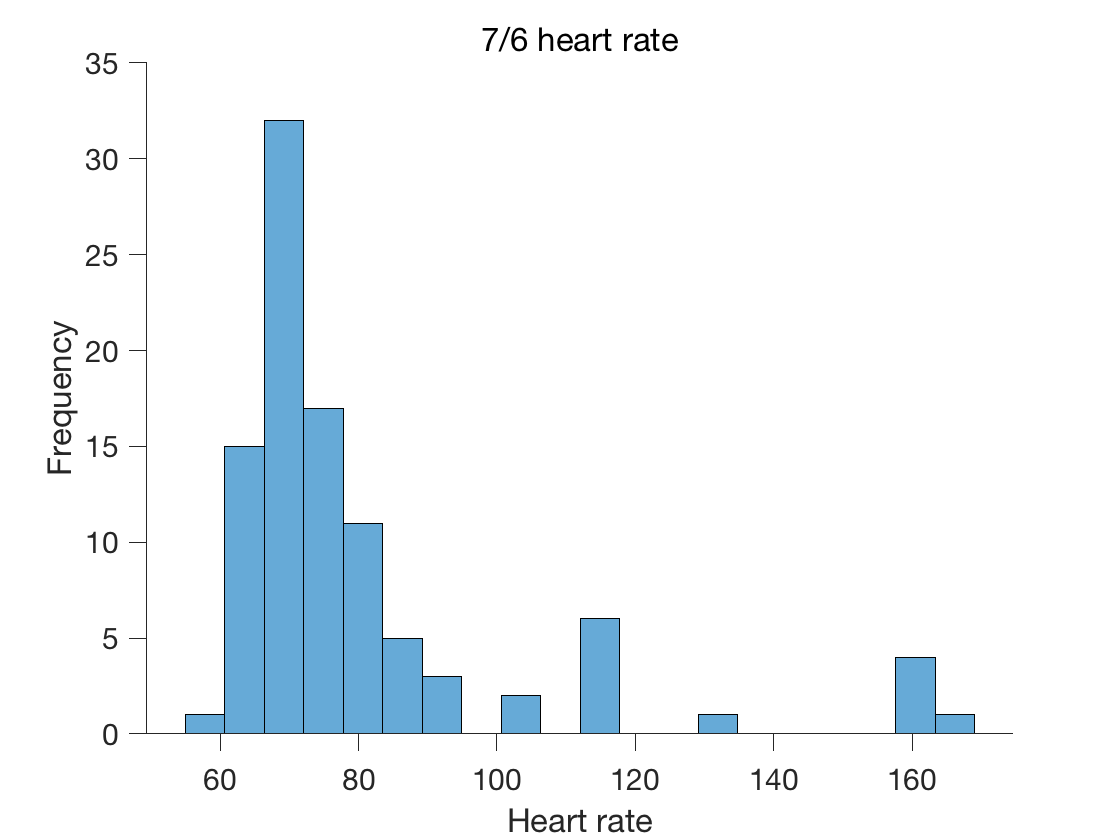

figure;
histogram(dat2(dat2(:,1)==6,3), 20);
xlabel('Heart rate');
ylabel('Frequency');
title('7/6 heart rate');
set(gca, 'fontsize', 15, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

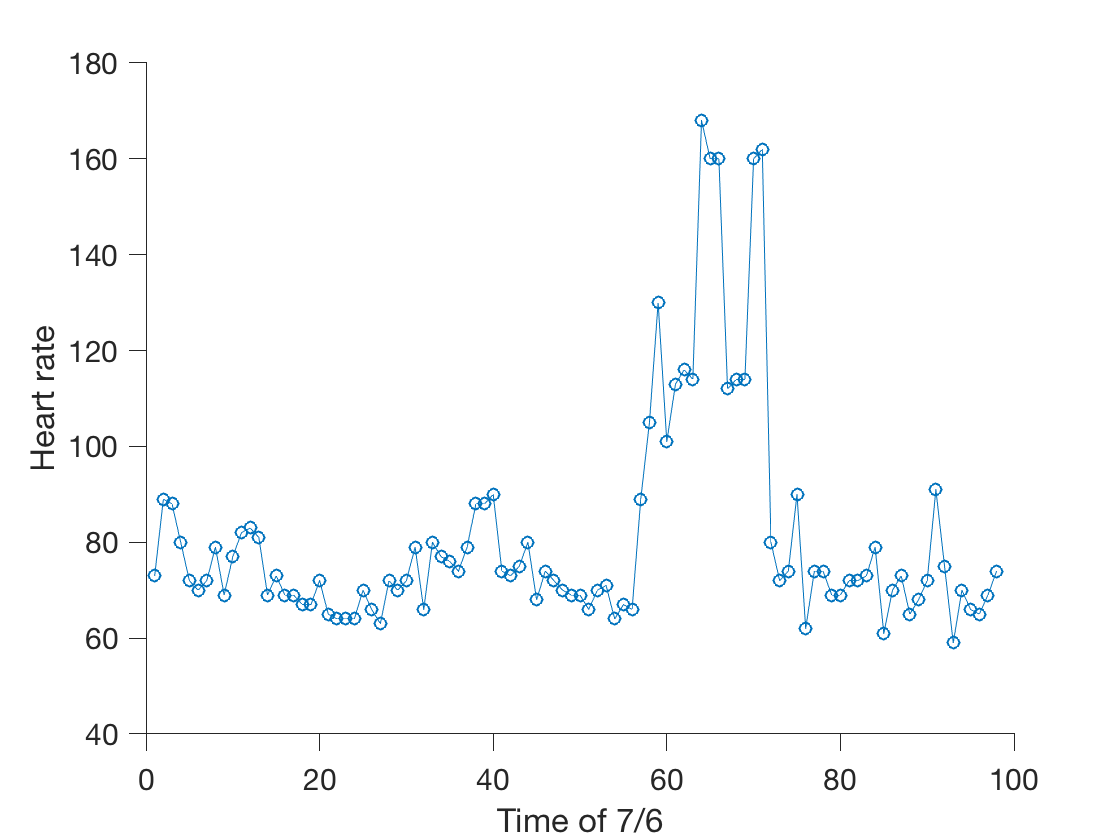

% timeplot
figure;
plot(dat2(dat2(:,1)==6,3), 'o-');
xlabel('Time of 7/6');
ylabel('Heart rate');
set(gca, 'fontsize', 15, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

## 3. LOESS timeplot

You will need the datviz toolbox for this. The toolbox is in the "script" directory.

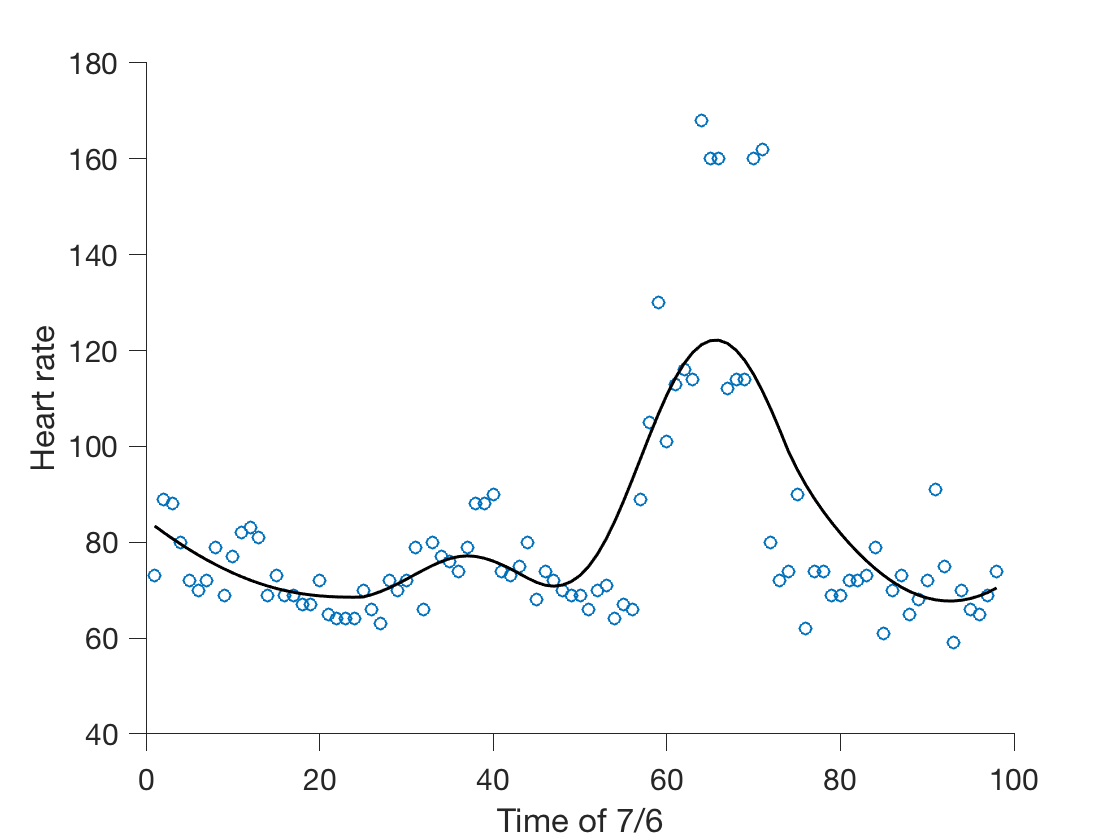

datavizdir = '/Users/clinpsywoo/Dropbox/2011-yr/teaching/Stats_2018Fall/scripts/dataviz';
addpath(datavizdir);

dat2viz = dat2(dat2(:,1)==6,3);

figure;
plot(dat2viz, 'o');
xlabel('Time of 7/6');
ylabel('Heart rate');
hold on; 
plot(loess((1:numel(dat2viz))', dat2viz, (1:numel(dat2viz))', .5, 2), 'color', ...
    'k', 'linewidth', 1.5);
set(gca, 'fontsize', 15, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

## 4. Rescaling and normal probability plot

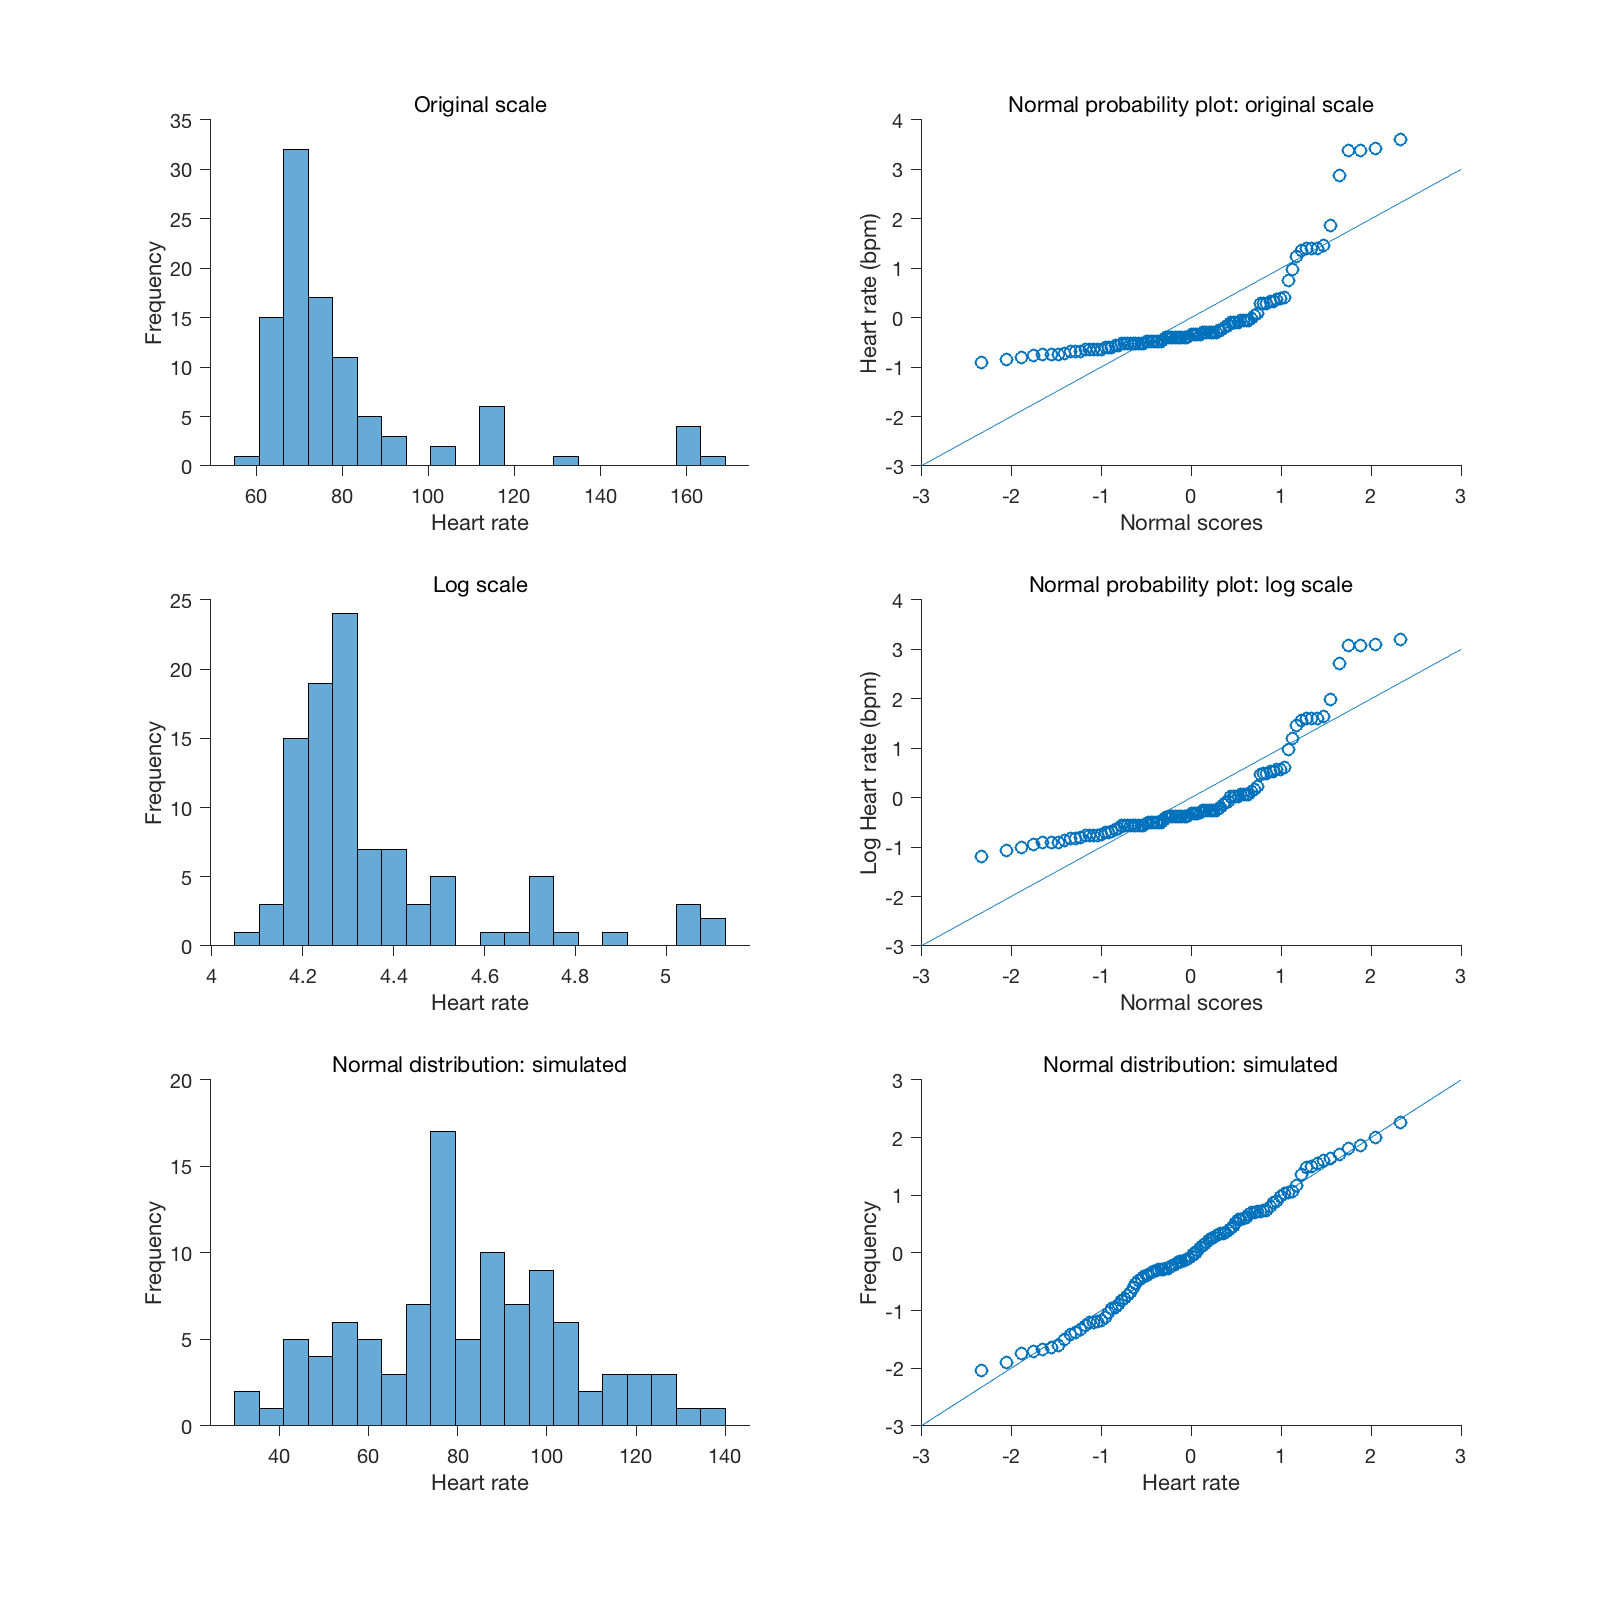

% Original scale
dat2viz = dat2(dat2(:,1)==6,3);

figure;
set(gcf, 'position', [1   154   807   801]);

subplot(3,2,1);
histogram(dat2viz, 20);
xlabel('Heart rate');
ylabel('Frequency');
title('Original scale');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

subplot(3,2,2);
zdat2viz = zscore(dat2viz);
for i = 1:100
    x(i,:)  = norminv(i/100,0,1);
    y(i,:) = prctile(zdat2viz,i);
end
scatter(x,y);
xlim = get(gca, 'xlim');
hold on;
line(xlim, xlim);

xlabel('Normal scores');
ylabel('Heart rate (bpm)');
title('Normal probability plot: original scale');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

% Log scale

dat2viz = log(dat2(dat2(:,1)==6,3));

subplot(3,2,3);
histogram(dat2viz, 20);
xlabel('Heart rate');
ylabel('Frequency');
title('Log scale');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

subplot(3,2,4);
zdat2viz = zscore(dat2viz);
for i = 1:100
    x(i,:)  = norminv(i/100,0,1);
    y(i,:) = prctile(zdat2viz,i);
end
scatter(x,y);
xlim = get(gca, 'xlim');
hold on;
line(xlim, xlim);

xlabel('Normal scores');
ylabel('Log Heart rate (bpm)');
title('Normal probability plot: log scale');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

% Data from normal distribution: simulated data

subplot(3,2,5);
simul_dat = normrnd(mean(dat2(dat2(:,1)==6,3)), std(dat2(dat2(:,1)==6,3)), 100, 1);
histogram(simul_dat, 20);
xlabel('Heart rate');
ylabel('Frequency');
title('Normal distribution: simulated');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);

subplot(3,2,6);
zdat2viz = zscore(simul_dat);
for i = 1:100
    x(i,:)  = norminv(i/100,0,1);
    y(i,:) = prctile(zdat2viz,i);
end
scatter(x,y);
xlim = get(gca, 'xlim');
hold on;
line(xlim, xlim);

xlabel('Heart rate');
ylabel('Frequency');
title('Normal distribution: simulated');
set(gca, 'fontsize', 10, 'box', 'off', 'tickdir', 'out', 'ticklength', [.02, .02]);